# 7.4 典型窗函数与窗函数法设计步骤：六种窗、表 7.2.2 复现、教材例 7.13—7.16（低通、高通、带通、带阻）

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。窗函数自写（只用基础 MATLAB 的 besseli），不依赖工具箱。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if isempty(here), here = pwd; end
outdir = fullfile(here, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：六种窗（N=51）：矩形、三角、汉宁、汉明、布莱克曼、凯塞（β=7.865，对应 −80 dB）

N = 51; wnames = {'矩形', '三角', '汉宁', '汉明', '布莱克曼', '凯塞 β=7.865'};
W = [win('rect', N); win('triang', N); win('hann', N); win('hamming', N); win('blackman', N); win('kaiser', N, 7.865)];

## 演示2：窗的频谱：主瓣宽度与最高旁瓣（教材表 7.2.2 的“旁瓣峰值”列）

w = linspace(0, pi, 16384); WdB = zeros(6, numel(w)); sidelobe = zeros(1, 6); mainlobe = zeros(1, 6);
for i = 1:6
    Wf = abs(polyval(fliplr(W(i, :)), exp(-1i*w))); WdB(i, :) = 20*log10(Wf/Wf(1));
    [~, lmin] = local_maxima(-Wf); mainlobe(i) = 2*w(lmin(1));                 % 主瓣宽 = 2×第一零点
    sidelobe(i) = max(WdB(i, w > w(lmin(1))));                                 % 第一零点之外的最高旁瓣
end

## 演示3：同一个理想低通（ωc=0.5π，N=51）用六种窗：阻带最小衰减对照表 7.2.2（−21/−25/−44/−53/−74/−80 dB）

wc = 0.5*pi; alpha = (N - 1)/2; hd = ideal_lp(wc, alpha, 0:N-1);
HdB = zeros(6, numel(w)); stopAtt = zeros(1, 6); transW = zeros(1, 6);
for i = 1:6
    h = hd.*W(i, :); Hf = abs(polyval(fliplr(h), exp(-1i*w))); HdB(i, :) = 20*log10(Hf/max(Hf));
    [~, lmin] = local_maxima(-Hf); i1 = lmin(find(w(lmin) > wc, 1));           % 阻带第一个谷
    stopAtt(i) = -max(HdB(i, w > w(i1)));                                      % 之后的最高旁瓣
    transW(i) = (w(find(Hf < 10^(-stopAtt(i)/20), 1)) - w(find(Hf < 1 - 10^(-stopAtt(i)/20), 1)))/pi;   % 从 1−δ 降到 δ 的宽度（π 为单位）
end
tableAtt = [21 25 44 53 74 80];

## 演示4：设计步骤（教材 7.2.4）：例 7.13 低通、例 7.14 高通、例 7.15 带通、例 7.16 带阻

例 7.13：ωp=0.3π、ωs=0.5π、As=40 dB → 汉宁窗（44 dB），N=⌈6.6π/Δω⌉+1 取奇数，ωc=(ωp+ωs)/2

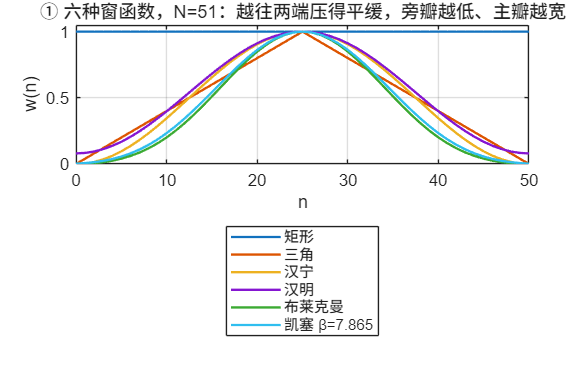

[h13, N13] = design_lp(0.3*pi, 0.5*pi, 'hann', 6.6);
[att13, rip13] = measure(h13, w, 0.3*pi, 0.5*pi, 'lp');
% 例 7.14：高通，ωp=0.4π、ωs=0.2π、As=50 dB → 汉明窗（53 dB），hd = δ(n−α) − 低通
[h14, N14] = design_hp(0.4*pi, 0.2*pi, 'hamming', 6.6);
[att14, rip14] = measure(h14, w, 0.4*pi, 0.2*pi, 'hp');
% 例 7.15：带通，fs=20 kHz，通带 3—5 kHz，阻带 ≤2 kHz、≥6 kHz，As=55 dB → 布莱克曼窗（74 dB），N=⌈11π/Δω⌉+1
fs15 = 20000; wp1 = 2*pi*3000/fs15; wp2 = 2*pi*5000/fs15; ws1 = 2*pi*2000/fs15; ws2 = 2*pi*6000/fs15;
[h15, N15] = design_bp(wp1, wp2, ws1, ws2, 'blackman', 11);
[att15, rip15] = measure(h15, w, [wp1 wp2], [ws1 ws2], 'bp');
% 例 7.16：带阻，fs=250 Hz，通带 ≤15 Hz、≥80 Hz，阻带 40—60 Hz，As=50 dB → 汉明窗
fs16 = 250; vp1 = 2*pi*15/fs16; vp2 = 2*pi*80/fs16; vs1 = 2*pi*40/fs16; vs2 = 2*pi*60/fs16;
[h16, N16] = design_bs(vp1, vp2, vs1, vs2, 'hamming', 6.6);
[att16, rip16] = measure(h16, w, [vp1 vp2], [vs1 vs2], 'bs');
% 教材参数（汉明、N=43）实测阻带只有约 47.5 dB，达不到 50 dB：把 N 逐步加大到达标为止
N16fix = N16; att16fix = att16;
while att16fix < 50
    N16fix = N16fix + 2; a16 = (N16fix - 1)/2; n16 = 0:N16fix-1; w1 = (vp1 + vs1)/2; w2 = (vp2 + vs2)/2;
    hd16 = -(ideal_lp(w2, a16, n16) - ideal_lp(w1, a16, n16)); hd16(n16 == a16) = 1 - (w2 - w1)/pi;
    att16fix = measure(hd16.*win('hamming', N16fix), w, [vp1 vp2], [vs1 vs2], 'bs');
end
H13 = 20*log10(abs(polyval(fliplr(h13), exp(-1i*w)))); H14 = 20*log10(abs(polyval(fliplr(h14), exp(-1i*w))));

if ~LIVE, f1 = figure('Name','04 窗函数设计','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(0:N-1, W.', 'LineWidth', 1.4); grid on; xlabel('n'); ylabel('w(n)'); ylim([0 1.05]);
title(sprintf('① 六种窗函数，N=%d：越往两端压得平缓，旁瓣越低、主瓣越宽', N)); legend(wnames);

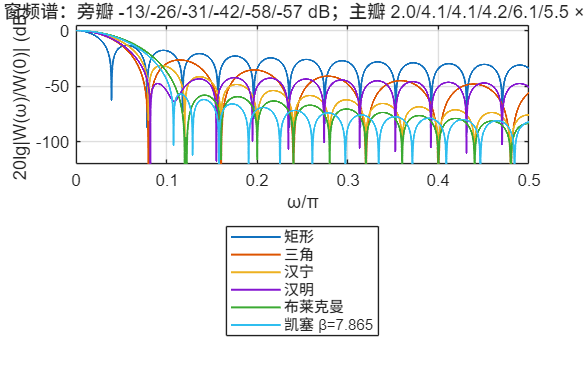

newpanel(); plot(w/pi, WdB.', 'LineWidth', 1.2); grid on; xlim([0 0.5]); ylim([-120 5]); xlabel('ω/π'); ylabel('20lg|W(ω)/W(0)| (dB)');
title(sprintf('② 窗频谱：旁瓣 %.0f/%.0f/%.0f/%.0f/%.0f/%.0f dB；主瓣 %.1f/%.1f/%.1f/%.1f/%.1f/%.1f ×2π/N', sidelobe, mainlobe*N/(2*pi)));
legend(wnames);

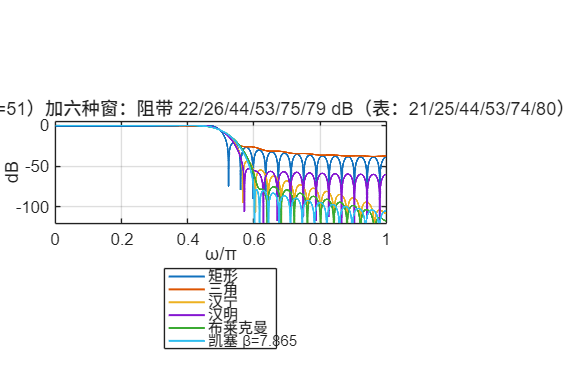

newpanel(); plot(w/pi, HdB.', 'LineWidth', 1.2); grid on; ylim([-120 5]); xlabel('ω/π'); ylabel('dB');
title(sprintf('③ 同一低通（N=51）加六种窗：阻带 %.0f/%.0f/%.0f/%.0f/%.0f/%.0f dB（表：21/25/44/53/74/80）', stopAtt));
legend(wnames);

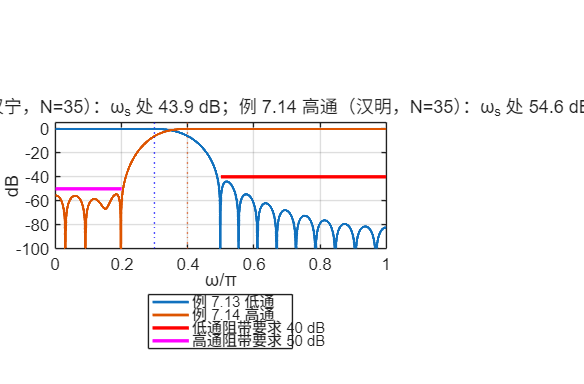

newpanel(); plot(w/pi, H13, 'LineWidth', 1.6); hold on; plot(w/pi, H14, 'LineWidth', 1.6);
plot([0.5 1], [-40 -40], 'r-', 'LineWidth', 2); plot([0 0.2], [-50 -50], 'm-', 'LineWidth', 2); xline(0.3, 'b:'); xline(0.4, ':', 'Color', [0.85 0.33 0.1]);
grid on; ylim([-100 5]); xlabel('ω/π'); ylabel('dB');
title(sprintf('④ 例 7.13 低通（汉宁，N=%d）：ω_s 处 %.1f dB；例 7.14 高通（汉明，N=%d）：ω_s 处 %.1f dB', N13, att13, N14, att14));
legend('例 7.13 低通', '例 7.14 高通', '低通阻带要求 40 dB', '高通阻带要求 50 dB');

if ~LIVE, sgtitle('窗函数法：先按阻带衰减选窗，再按过渡带定 N，理想 h_d(n) 乘窗就是设计结果'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '04-windows-design.png'), 'Resolution', 150); end

## 教师核验

assert(all(abs(stopAtt - tableAtt) < 4), '六种窗的阻带衰减与表 7.2.2 不符');
assert(abs(sidelobe(1) + 13.3) < 0.5 && sidelobe(4) < -40 && sidelobe(5) < -55, '窗旁瓣不符');
assert(N13 == 35 && N14 == 35 && N15 == 111 && N16 == 43, '例 7.13—7.16 的 N 不符');
assert(att13 >= 40 && att14 >= 50 && att15 >= 55 && att16fix >= 50 && att16 < 50, '例 7.13—7.16 阻带核验不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'N', N, 'window_names', {wnames}, 'window_sidelobe_dB', sidelobe, 'mainlobe_width_x2piN', mainlobe*N/(2*pi), ...
    'lowpass_stop_att_dB', stopAtt, 'table_722', tableAtt, 'lowpass_transition_over_pi', transW, ...
    'ex713_N', N13, 'ex713_att_ws_dB', att13, 'ex713_pass_ripple_dB', rip13, 'ex714_N', N14, 'ex714_att_ws_dB', att14, 'ex714_pass_ripple_dB', rip14, ...
    'ex715_N', N15, 'ex715_att_dB', att15, 'ex715_pass_ripple_dB', rip15, 'ex716_N', N16, 'ex716_att_dB', att16, 'ex716_pass_ripple_dB', rip16, 'ex716_N_needed_for_50dB', N16fix, 'ex716_att_dB_fixed', att16fix, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-windows-design.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

                matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                        run_at: '2026-09-18 22:16:34'
                             N: 51
                  window_names: {'矩形'  '三角'  '汉宁'  '汉明'  '布莱克曼'  '凯塞 β=7.865'}
            window_sidelobe_dB: [-13.2502 -26.4292 -31.4675 -42.3129 -58.1124 -57.0535]
          mainlobe_width_x2piN: [1.9985 4.0811 4.0811 4.1838 6.1201 5.4913]
           lowpass_stop_att_dB: [21.6871 26.0582 43.9997 53.1351 75.3547 78.8239]
                     table_722: [21 25 44 53 74 80]
    lowpass_transition_over_pi: [0.0363 0.1393 0.1250 0.1348 0.2235 0.1996]
                       ex713_N: 35
               ex713_att_ws_dB: 43.9436
          ex713_pass_ripple_dB: 0.0713
                       ex714_N: 35
               ex714_att_ws_dB: 54.6147
          ex714_pass_ripple_dB: 0.0288
                       ex715_N: 111
                  ex715_att_dB: 73.5820
          ex715_pass_ripple_dB: 0.0033
                       ex716_N: 43
             

## 本地函数

function wv = win(kind, N, beta)
n = 0:N-1; M = N - 1;
switch kind
    case 'rect',     wv = ones(1, N);
    case 'triang',   wv = 1 - abs(2*n - M)/M;                                   % 三角（巴特利特）窗
    case 'hann',     wv = 0.5 - 0.5*cos(2*pi*n/M);
    case 'hamming',  wv = 0.54 - 0.46*cos(2*pi*n/M);
    case 'blackman', wv = 0.42 - 0.5*cos(2*pi*n/M) + 0.08*cos(4*pi*n/M);
    case 'kaiser',   wv = besseli(0, beta*sqrt(1 - (2*n/M - 1).^2))/besseli(0, beta);   % 教材式 (7.2.10)
end
end

function h = ideal_lp(wc, alpha, n)
h = zeros(size(n)); i = abs(n - alpha) > 1e-12;
h(i) = sin(wc*(n(i) - alpha))./(pi*(n(i) - alpha)); h(~i) = wc/pi;
end

function N = choose_N(Bt, factor)
N = ceil(factor*pi/Bt) + 1; if mod(N, 2) == 0, N = N + 1; end                  % 与教材 Python 代码一致：取奇数
end

function [h, N] = design_lp(wp, ws, kind, factor)
N = choose_N(abs(ws - wp), factor); alpha = (N - 1)/2; wc = (wp + ws)/2;
h = ideal_lp(wc, alpha, 0:N-1).*win(kind, N);
end

function [h, N] = design_hp(wp, ws, kind, factor)
N = choose_N(abs(wp - ws), factor); alpha = (N - 1)/2; wc = (wp + ws)/2; n = 0:N-1;
hd = -ideal_lp(wc, alpha, n); hd(n == alpha) = 1 - wc/pi;                       % δ(n−α) − 低通
h = hd.*win(kind, N);
end

function [h, N] = design_bp(wp1, wp2, ws1, ws2, kind, factor)
N = choose_N(min(abs(wp1 - ws1), abs(wp2 - ws2)), factor); alpha = (N - 1)/2; n = 0:N-1;
w1 = (wp1 + ws1)/2; w2 = (wp2 + ws2)/2;
hd = ideal_lp(w2, alpha, n) - ideal_lp(w1, alpha, n);                            % 两个低通相减
h = hd.*win(kind, N);
end

function [h, N] = design_bs(wp1, wp2, ws1, ws2, kind, factor)
N = choose_N(min(abs(wp1 - ws1), abs(wp2 - ws2)), factor); alpha = (N - 1)/2; n = 0:N-1;
w1 = (wp1 + ws1)/2; w2 = (wp2 + ws2)/2;
hd = -(ideal_lp(w2, alpha, n) - ideal_lp(w1, alpha, n)); hd(n == alpha) = 1 - (w2 - w1)/pi;   % 全通 − 带通
h = hd.*win(kind, N);
end

function [att, rip] = measure(h, w, wp, ws, kind)
% 阻带最小衰减（dB）与通带最大起伏（dB）
Hf = abs(polyval(fliplr(h), exp(-1i*w)));
switch kind
    case 'lp', sb = w >= ws; pb = w <= wp;
    case 'hp', sb = w <= ws; pb = w >= wp;
    case 'bp', sb = w <= ws(1) | w >= ws(2); pb = w >= wp(1) & w <= wp(2);
    case 'bs', sb = w >= ws(1) & w <= ws(2); pb = w <= wp(1) | w >= wp(2);
end
att = -20*log10(max(Hf(sb))); rip = 20*log10(max(Hf(pb))) - 20*log10(min(Hf(pb)));
end

function [pk, loc] = local_maxima(x)
loc = find(x(2:end-1) > x(1:end-2) & x(2:end-1) >= x(3:end)) + 1; pk = x(loc);
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end